# Uniaxial Stress and Strain

## Uniaxial Stress

Consider a body in static equilibrium with forces applied to it. Although it does not move, the forces acting on it induce internal forces between different regions of the body. These internal forces are often characterized using stress. The stress is, roughly speaking, the amount of force acting on a unit area of an internal surface. However, this rough definition must be refined due to the complex geometry of 3D surfaces and force vectors. For now, consider a simple case: a body that is being forced along a single axis.

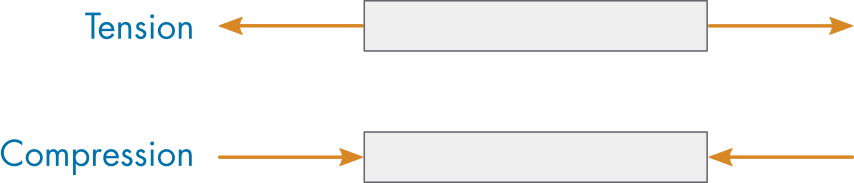

*Uniaxial forces acting on a bar. If the forces pull outward, the bar is under tension. Compressive forces point inward.*

**Definition.** For a simple uniaxial loading, the stress is defined as the force per unit area acting on a perpendicular surface:


$$\sigma = \frac{F}{A}$$


By convention, tension produces positive stress ($\sigma > 0$) while compression produces negative stress ($\sigma < 0$).

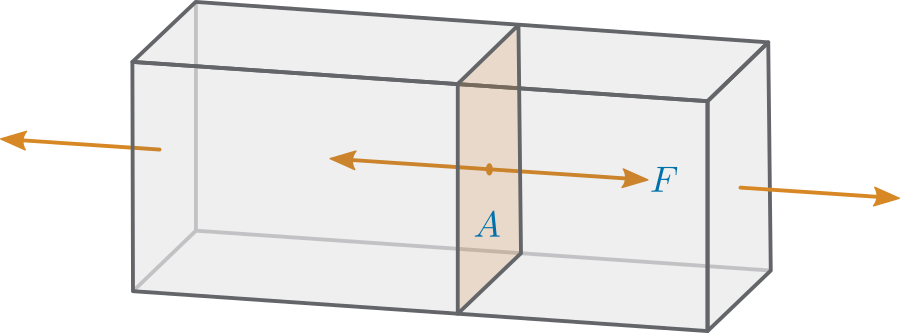

*The stress on the illustrated plane (which is perpendicular to the applied force) in this tensioned bar is *$\sigma = F/A$*.*

  **Activity. **The code below visualizes the stress on a plane in a uniaxially forced bar. 

**Task 1.** Run this section to show the illustration. Then, adjust the sliders to view the stress under different loading conditions and bar sizes.

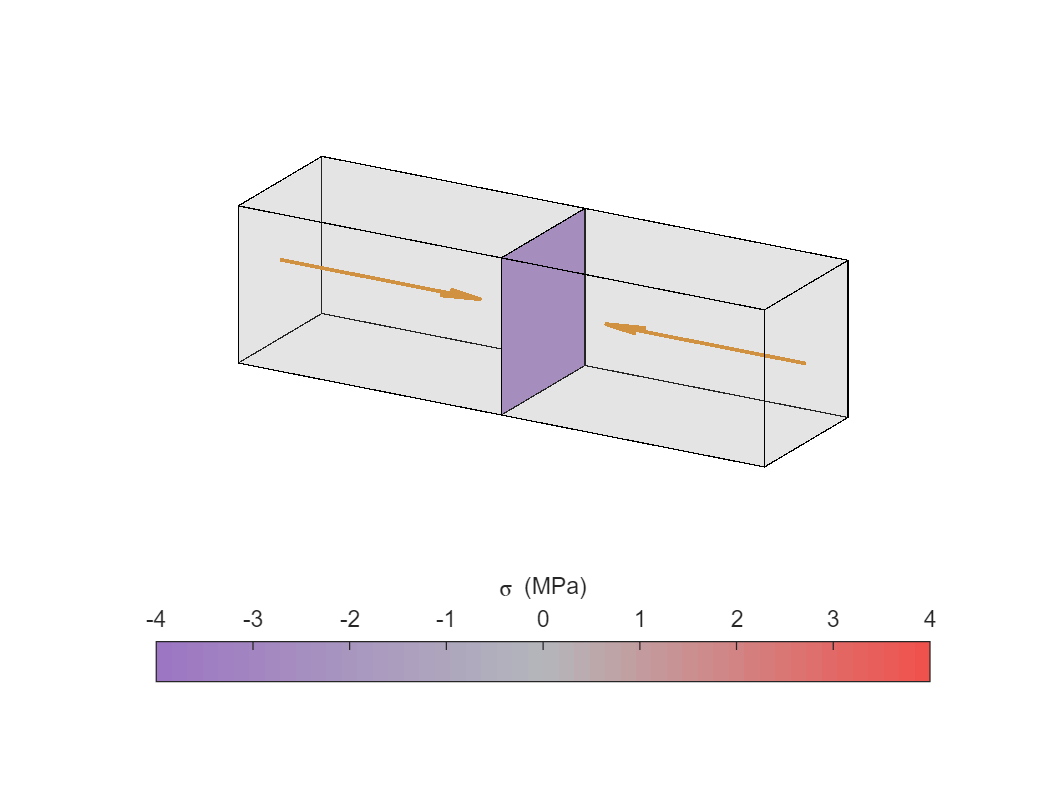

F =-950 * 1e3; % Axial force (N)
w =0.55; % Width (m)
l = 2;   % Length (m)
visualizeAxialStress(F,l,w);

**Task 2. **Compute the stress if $w = 0.75$ m and $F = 1000 \times 10^3$ N. Write your answer in terms of MPa, where $1$ MPa = $10^6$ N/m$^2$.

**Task 3. **The slider allows values of $w$ between 0.5 m and 1 m. The force slider varies from -1000 kN to 1000 kN. Within these value ranges, what is greatest stress experienced by the bar under tension? What is the greatest stress experienced by the bar under compression?

## Longitudinal Strain

When a body is stressed it will typically deform. For example, if a bar is placed under tension, it will elongate. This deformation may be very small for stiff materials, like ceramics, or very large for elastic materials, like rubber. Deformation is typically quantified in terms of strain.

When a body is uniaxially stressed, it will typically produce a longitudinal strain that characterizes an increase or decrease in length. 

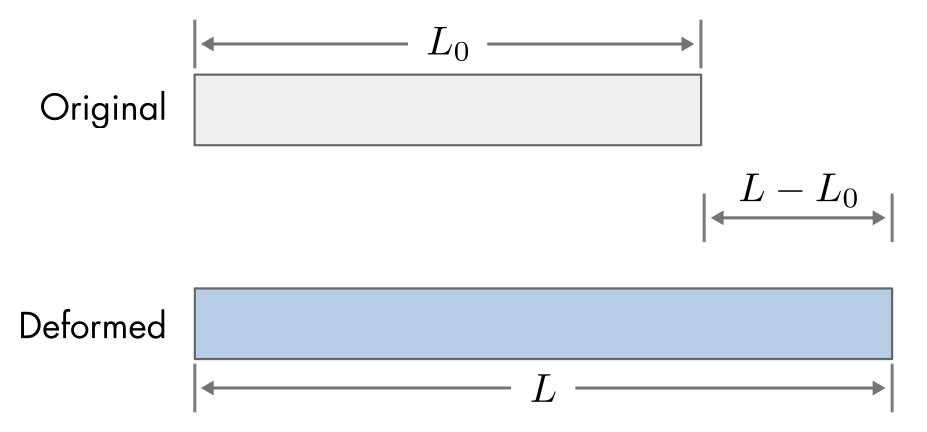

*A bar elongated from length *$L_0$ *to *$L$

**Definition.** The longitudinal strain is defined as the ratio of the change in length to the original length:


$$\epsilon = \frac{L - L_0}{L_0}$$


  **Activity.  **The code below visualizes the elongation of a bar.

**Task 1. **Run this section to visualize the bar. Then, change the deformed length by adjusting the slider.

**Task 2. **Set the deformed length `L = 3`. What is the value of the longitudinal strain, $\epsilon$? 

**Task 3. **Repeat **Task 2** for `L = 1.8`.

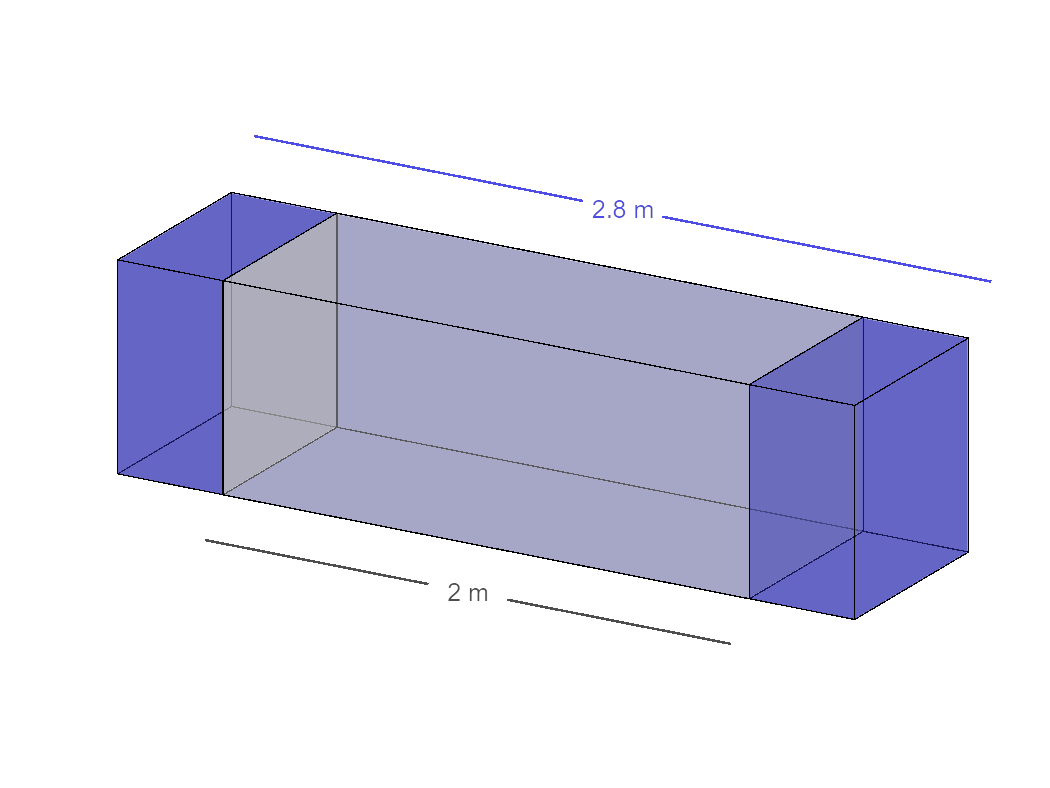

L = 2.8; % Deformed length (m)
L0 = 2;   % Initial length (m)
W0 = 0.75;   % Initial width (m)
visualizeAxialStrain(L,L0,W0,0);

## Hooke's Law

If a bar is uniaxially tensioned, how much far will it stretch? The overall relationship between the stress ($\sigma$) and strain ($\epsilon$) for a material can be characterized using a stress-strain curve.

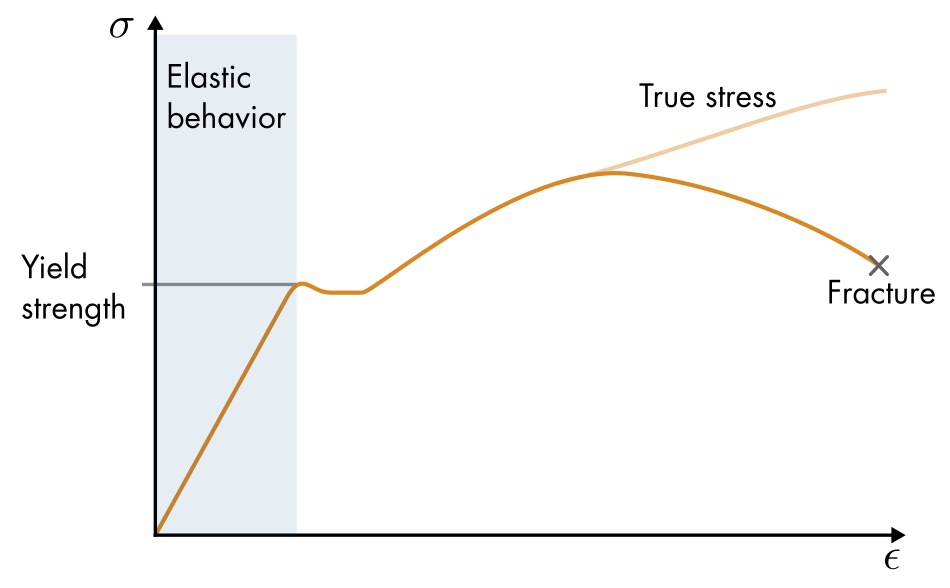

*Generic stress-strain curve for a uniaxially loaded bar. For large strains, the bar experiences necking, substantially reducing the cross-sectional area. In this case, while the stress appears to decrease when measured relative to the intial cross-sectional area *$A_0$*, the true stress actually increases.*

Initially, a tensioned bar will stretch uniformly based on the Young's modulus of the material, which characterizes its stiffness. This is elastic behavior. Elastic stretches are reversible; if the loading is removed without further increases in stress, the bar will return to its original size. If the loading is increased, the bar will experience strain-hardening and necking, before finally fracturing. Strain-hardening is partially irreversible, while necking and fracturing are irreversible.

For many analyses, it is sufficient to model only the elastic behavior of the material. The elastic behavior is modeled by a linear relationship between stress and strain known as Hooke's law:

    
$$\sigma= E \epsilon$$


For uniaxial loading, $\sigma$ is the normal stress and $\epsilon$ the longitudinal strain. $E$ is the Young's modulus of the material that determines the stiffness. For example, steel typically has a Young's modulus in the neighborhood of 200 GPa, while rubbers have a Young's modulus ion the neighborhood of 0.1 GPa (or less, for a stretchy silicone rubber).

  **Activity.  **The code below visualizes the elongation of a bar that has been uniaxially loaded. Note that this visualization assumes that the bar displays elastic behavior. The strain is computed using Hooke's law.

**Task 1. **Run this section to visualize the bar. 

**Task 2. **If you decrease the Young's modulus (E), do you expect to see more or less deformation? Test your hypothesis.

**Task 3. **What values of the sliders produce the greatest compression? 

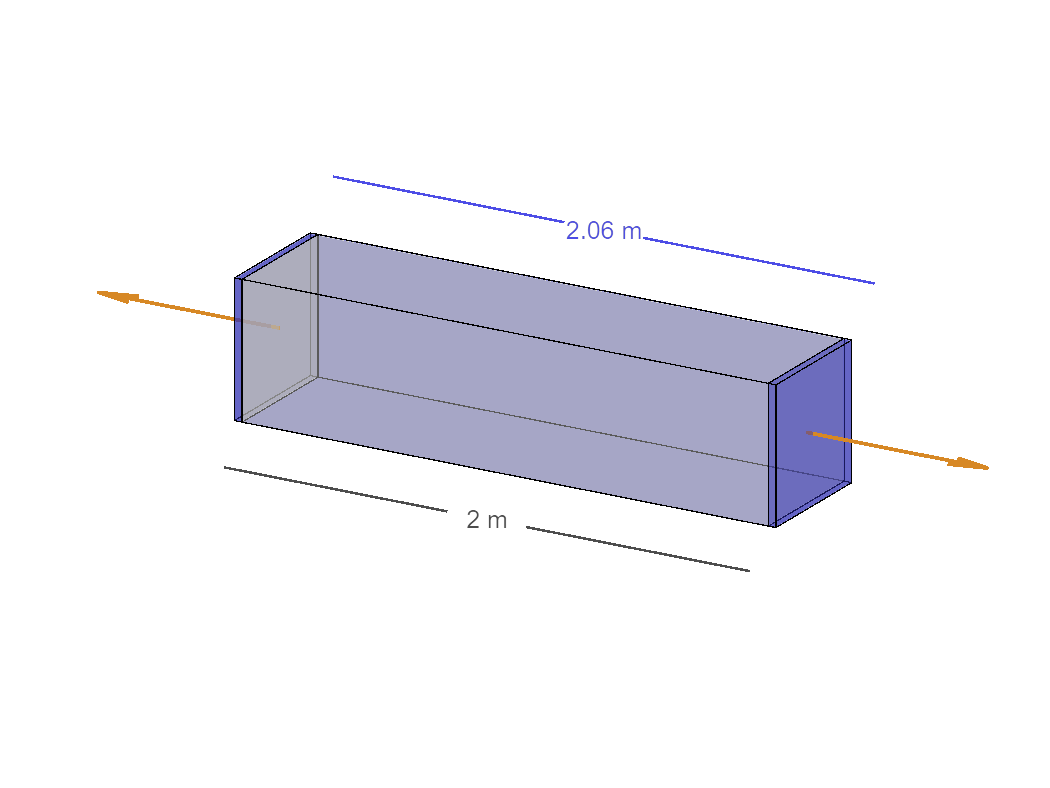

F =860* 1e6; % Axial force (N)
E = 120* 1e9; % Young's modulus (Pa)
W0 =0.5; % Width (m)
L0 = 2;   % Initial length (m)
visualizeHookes(F,E,L0,W0,0)

**Exercise. **A steel bar with a Young's modulus of 200 MPa and a cross sectional area of 0.25 m$^2$ is tensioned by a force of $500 \times 10^6$ N. Assuming Hooke's law, compute the value of the strain $\epsilon$. If the original length of the bar is 2 m, what will the final length be?

**Helper Functions**

function visualizeAxialStress(F,L0,W0)
    cla
    
    % Calculations
    N = 50;
    sigmaL = F/(W0*W0); % In N/m^2 = Pa
    sigMax = 1000e3/0.5^2;
    sigIdx = round(N/2*sigmaL/abs(sigMax)) + N/2 + 1;
    sigIdx(sigIdx < 1) = 1;
    sigIdx(sigIdx > N) = N;
    purpleRed = purpleRedMap(N);
    planeColor = purpleRed(sigIdx ,:);

    % Visualization parameters
    cubeEdgeAlpha = 1;
    cubeAlpha = 0.2;
    cubeColors = [1 1 1]*0.7;
    forceColor = [215 136 37]/255;
    axLims = [-1 1 -2 2 -1.4 0.6]*0.6;
    Fscale = 0.8e-6;
    arrowheadScale = 0.4;
    Flw = 1.5;
    
    % Cube and deformations
    [vertices,faces,~] = cubeValues();
    vertices = vertices - 0.5;
    vertices(:,2) = vertices(:,2)*L0;
    vertices(:,[1,3]) = vertices(:,[1,3])*W0;

    % Plane
    yp = [0 0 0 0 0];
    xp = W0/2*[-1 1 1 -1 -1];
    zp = W0/2*[-1 -1 1 1 -1];

    % Create plot
    patch("Vertices",vertices,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
        "FaceColor","Flat","FaceVertexCData",cubeColors,"FaceAlpha",cubeAlpha);
    patch("XData",xp,"YData",yp,"ZData",zp,"FaceColor",planeColor)
    hold on

    % Force vectors
    ymneg = mean(vertices([1 2 5 6],2));
    quiver3(0,ymneg,0,0,-F*Fscale,0,"Color",forceColor,"LineWidth",Flw,...
        "AutoScale","off","MaxHeadSize",arrowheadScale/abs(F*Fscale))
    ympos = mean(vertices([3 4 7 8],2));
    quiver3(0,ympos,0,0,F*Fscale,0,"Color",forceColor,"LineWidth",Flw,...
        "AutoScale","off","MaxHeadSize",arrowheadScale/abs(F*Fscale))

    % Axis settings
    hold off
    view(120,20)
    axis equal
    axis(axLims)
    set(gca,"Clipping","off")
    axis off
    colormap(purpleRed)
    cbar = colorbar("location","south");
    ylabel(cbar,"\sigma (MPa)")
    clim([-1 1]*sigMax/1e6)
end

function visualizeAxialStrain(L,L0,W0,nu)
    clf

    % Calculations
    L = L + 1e-3;
    longStretch = L/L0;
    epsL = (L-L0)/L0; % Longitudinal strain
    epsT = - nu*epsL; % Transverse strain
    transverseStretch = epsT + 1 - 1e-3;
    
    % Visualization parameters
    cubeEdgeAlpha = 1;
    cubeAlpha = 0.5;
    cubeColors = [1 1 1]*0.7;
    cubeColorsDeformed = [50 50 180]/255;
    cubeAlphaDeformed = 0.5;
    axLims = [-1 1 -2 2 -0.7 1]*0.6;
    
    % Cube and deformations
    [vertices,faces,~] = cubeValues();
    vertices = vertices - 0.5;
    vertices(:,2) = vertices(:,2)*L0;
    vertices(:,[1,3]) = vertices(:,[1,3])*W0;
    verticesDeformed = vertices;
    verticesDeformed(:,2) = verticesDeformed(:,2)*longStretch;
    verticesDeformed(:,[1,3]) = verticesDeformed(:,[1,3])*transverseStretch;
    
    % Create plot
    patch("Vertices",vertices,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
        "FaceColor","Flat","FaceVertexCData",cubeColors,"FaceAlpha",cubeAlpha);
    hold on
    patch("Vertices",verticesDeformed,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
        "FaceColor","Flat","FaceVertexCData",cubeColorsDeformed,"FaceAlpha",cubeAlphaDeformed);

    % Label for L0
    xyz1 = vertices(2,:)';
    xyz2 = vertices(3,:)';
    offsetVector = [1; 0; -1]*0.12;
    labelText = num2str(L0,3) + " m";
    dimensionLabel(xyz1,xyz2,offsetVector,labelText,[0.3,0.3,0.3]);

    % Label for L
    xyz1 = verticesDeformed(5,:)';
    xyz2 = verticesDeformed(8,:)';
    offsetVector = -[1; 0; -1]*0.15;
    labelText = num2str(L,3) + " m";
    dimensionLabel(xyz1,xyz2,offsetVector,labelText,[0.3,0.3,0.9]);

    hold off
    view(120,20)
    axis equal
    axis(axLims)
    set(gca,"Clipping","off")
    axis off
end

function visualizeHookes(F,E,L0,W0,nu)
    
    % Compute strain using Hooke's law
    sigmaL = F/(W0*W0); % In N/m^2 = Pa
    epsL = sigmaL/E; % In     
    L = epsL*L0 + L0;

    % Visualize the strain
    visualizeAxialStrain(L,L0,W0,nu)

    % Properties
    forceColor = [215 136 37]/255;
    axLims = [-1 1 -2 2 -1 1]*0.6;
    Fscale = 0.8e-9;
    arrowheadScale = 0.4;
    Flw = 1.5;

    % Force vectors
    [vertices,faces,~] = cubeValues();
    vertices = vertices - 0.5;
    vertices(:,2) = vertices(:,2)*L0;
    vertices(:,[1,3]) = vertices(:,[1,3])*W0;
    ymneg = mean(vertices([1 2 5 6],2));
    hold on
    quiver3(0,ymneg,0,0,-F*Fscale,0,"Color",forceColor,"LineWidth",Flw,...
        "AutoScale","off","MaxHeadSize",arrowheadScale/abs(F*Fscale))
    ympos = mean(vertices([3 4 7 8],2));
    quiver3(0,ympos,0,0,F*Fscale,0,"Color",forceColor,"LineWidth",Flw,...
        "AutoScale","off","MaxHeadSize",arrowheadScale/abs(F*Fscale))
    hold off
    axis(axLims)
end

function dimensionLabel(xyz1,xyz2,offsetVector,labelText,color)
    mag = norm(xyz1-xyz2);
    xyzm = (xyz1 + xyz2)/2;
    xyzm1 = (xyz1*(0.5+0.15/mag) + xyz2*(0.5-0.15/mag));
    xyzm2 = (xyz1*(0.5-0.15/mag) + xyz2*(0.5+0.15/mag));
    plot3([xyz1(1),xyzm1(1),NaN,xyzm2(1),xyz2(1)]+offsetVector(1),...
          [xyz1(2),xyzm1(2),NaN,xyzm2(2),xyz2(2)]+offsetVector(2),...
          [xyz1(3),xyzm1(3),NaN,xyzm2(3),xyz2(3)]+offsetVector(3),...
          "-","Color",color,"LineWidth",1)

    xyzt = xyzm + offsetVector;

    text(xyzt(1),xyzt(2),xyzt(3),labelText,"Color",color,...
        "VerticalAlignment","middle","HorizontalAlignment","center");

end

function [vertices,faces,normals] = cubeValues()
    vertices = [0 0 0; 1 0 0; 1 1 0; 0 1 0;
                0 0 1; 1 0 1; 1 1 1; 0 1 1];
    faces = [1 2 3 4 1; 5 6 7 8 5; 1 2 6 5 1; 
             3 4 8 7 3; 1 4 8 5 1; 2 3 7 6 2];
    normals = [0 0 -1; 0 0 1; 0 -1 0; 0 1 0; -1 0 0; 1 0 0];
end

function purpleRed = purpleRedMap(N)
    % Creates a custom color map (red - black - green)
    baseColors = [121 91 150;...
                  138 140 144;...
                  184 63 59]*1.3/255;
    purpleRed = interp1([-1 0 1],baseColors,linspace(-1,1,N));
end